# Decision Trees

## What are decision trees? 

A **decision tree** algorithm constructs a set of decisions based on training data. Its structure is comprised of decision nodes connected by edges. Data points are processed by moving through a decision tree, which uses binary/ternary rules to calculate a target value. 

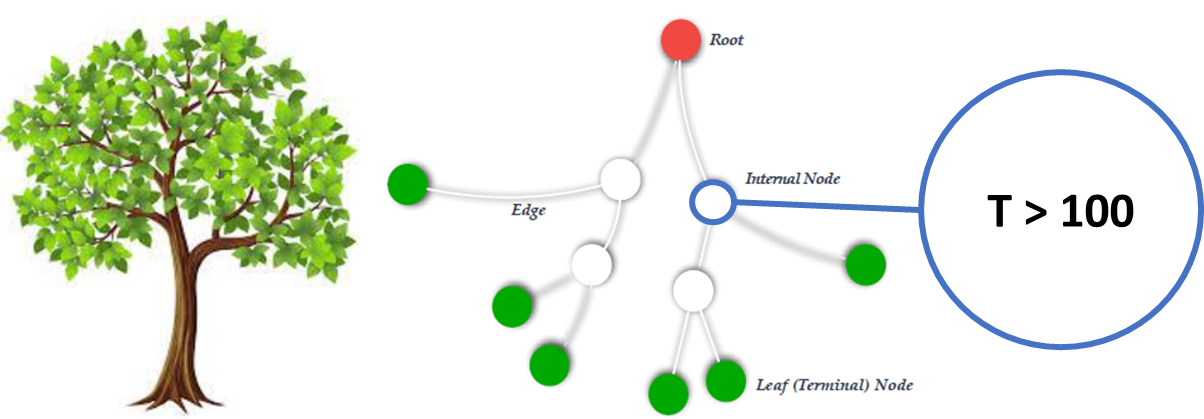

Advantages:

- Easy to visualize and interpret

- Structure is easily explainable

- Can be used for both classification and regression purposes

- Can work with missing data

- Naturally non-linear

## Decision trees for classification - a toy example

To explain how decision trees can be applied for a classification problem, we will use data pertaining to weather conditions and how this influences the likelihood that John will play tennis: 

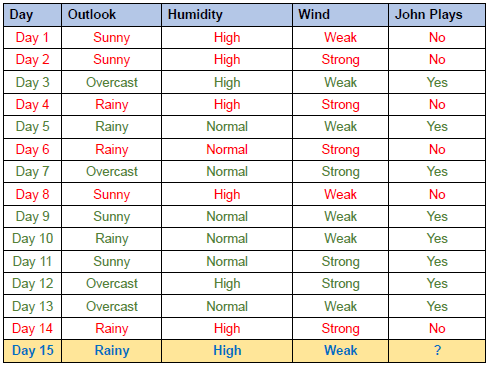

Based on data that has been recorded, we can derive a set of rules that gradually distinguish between classes (whether John plays tennis or not): 

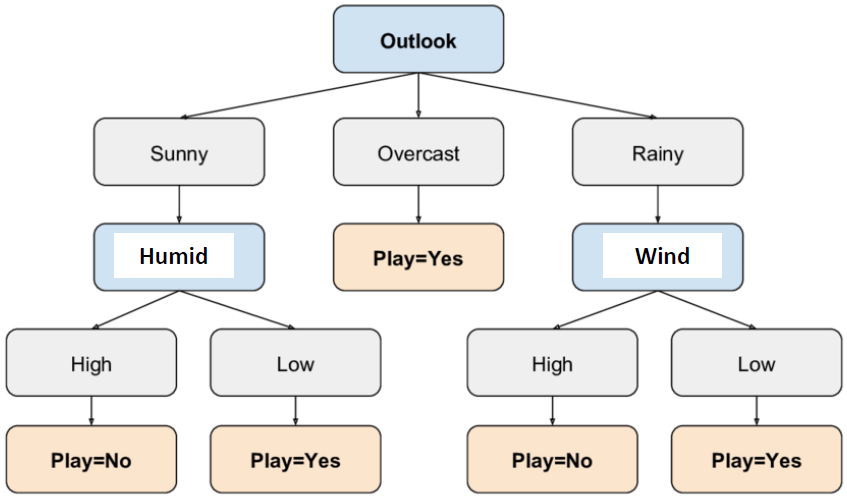

### How do we choose the best attributes? 

In principle, the best attributes are those that optimally separate the training examples as much as possible. There are multiple ways to quantitatively define this separation, but we'll specifically discuss entropy within this lesson.

**Entropy** is defined as lack of order or predictability. When applied with decision trees, we aim to identify the set of attributes that minimize entropy when predicting outcomes. Mathematically, we define entropy as: 


$$\mathrm{Entropy}=-\sum_i p\left(x_i \right){\mathrm{log}}_2 p\left(x_i \right)$$


where $p\left(x_i \right)$ denotes the probability for the outcome to be class $i$. By minimizing entropy, we maximize the separation between different classes. We can alternative think about this concept using a probability distribution: 

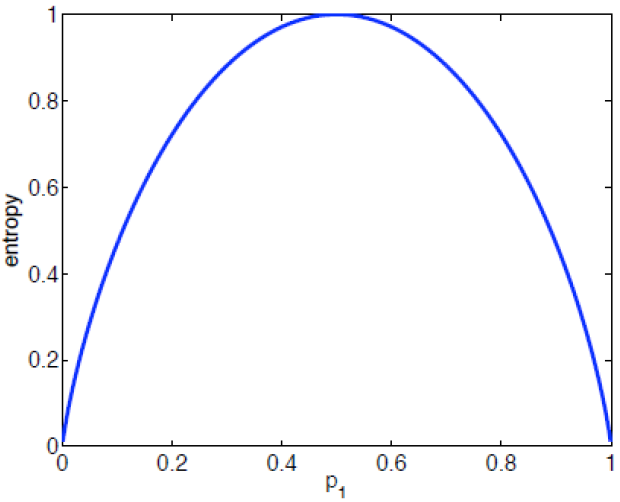

Using this perspective, greater deviation from uniformity in the probability distribution between classes results in lower entropy. 

### Hyperparameter tuning for decision trees

Sometimes, minimizing entropy (or another optimization function) does not yield the best decision tree model. For instance, a tree with each node corresponding to each data point has an entropy of 0 - but this model will perform poorly when applied with new data. To avoid this situation, we can customize **hyperparameters** that define tree size and complexity. Specific parameters include: 

- The depth of the tree: deep trees are more complex and may overfit

- The minimum number of samples in a node: each node should have at least 2 samples before it can split

- The maximum number of leaf nodes: too many nodes may lead to a model where each terminal node corresponds to a single data point

## In-class example: predicting diabetes using the Framingham dataset

To learn how to develop decision trees for classification in MATLAB, we'll use the Framingham dataset to predict whether a patient is diabetic or not. First, we'll load the data and define our inputs (X) and output (Y). We'll also subset them into training and testing sets: 

% Load the dataset
fram = readtable('frmgham2.xls');

% Extract all features except diabetes (column 10)
X = fram(:, [1:9, 11:14]);

% Define output variable (diabetes)
Y = fram.DIABETES;

% Subset data into training/testing sets via 30% holdout
idx = crossvalind('HoldOut', Y, 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

We'll now create a classification tree using the `fitctree` function and display its structure using the `view` function: 

% Create classification tree
Decision_Tree = fitctree(Xtrain, Ytrain) 

Decision_Tree =   ClassificationTree
           PredictorNames: {'RANDID'  'SEX'  'TOTCHOL'  'AGE'  'SYSBP'  'DIABP'  'CURSMOKE'  'CIGPDAY'  'BMI'  'BPMEDS'  'HEARTRTE'  'GLUCOSE'  'educ'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 8139


  Properties, Methods


% View tree structure as set of rules
view(Decision_Tree)

Decision tree for classification
  1  if GLUCOSE<139.5 then node 2 elseif GLUCOSE>=139.5 then node 3 else 0
  2  if GLUCOSE<118.5 then node 4 elseif GLUCOSE>=118.5 then node 5 else 0
  3  if GLUCOSE<176.5 then node 6 elseif GLUCOSE>=176.5 then node 7 else 1
  4  if TOTCHOL<441 then node 8 elseif TOTCHOL>=441 then node 9 else 0
  5  if RANDID<6.91538e+06 then node 10 elseif RANDID>=6.91538e+06 then node 11 else 0
  6  if BMI<31.18 then node 12 elseif BMI>=31.18 then node 13 else 1
  7  class = 1
  8  if GLUCOSE<96.5 then node 14 elseif GLUCOSE>=96.5 then node 15 else 0
  9  if AGE<67 then node 16 elseif AGE>=67 then node 17 else 0
 10  if SYSBP<198.5 then node 18 elseif SYSBP>=198.5 then node 19 else 0
 11  if SYSBP<134 then node 20 elseif SYSBP>=134 then node 21 else 0
 12  if DIABP<85.5 then node 22 elseif DIABP>=85.5 then node 23 else 1
 13  class = 1
 14  if educ<3.5 then node 24 elseif educ>=3.5 then node 25 else 0
 15  if AGE<64.5 then node 26 elseif AGE>=64.5 then node 27 else 0


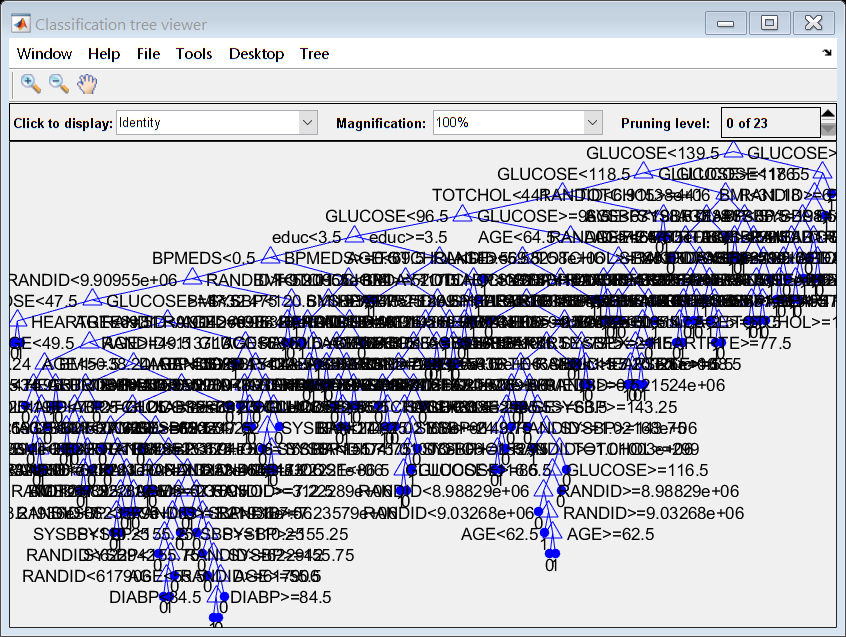

% View tree structure graphically
view(Decision_Tree, 'mode', 'graph')

### Assessing and improving tree quality

The **resubstitution error** is the difference between predicted vs. actual outcomes of the input training data. If the resubstitution error is high, you cannot expect the predictions of the tree to be good. However, having low resubstitution error does not guarantee good predictions for new data. The resubstitution error is often an overly optimistic estimate of the predictive error on new data.

% Examine the resubsitution error
resuberror = resubLoss(Decision_Tree); 
fprintf('The resubstitution classification error is %4.2f%% \n', 100 * resuberror)

The resubstitution classification error is 1.99% 


We can also assess our model quality via **cross-validation** (CV). In MATLAB, the `cvloss` function performs a 10-fold CV (default) and reports the average test set error: 

% Perform 10-fold cross-validation
cverror = cvloss(Decision_Tree); 
fprintf('The 10-fold cross-validation error is %4.2f%% \n', 100 * cverror)

The 10-fold cross-validation error is 4.82% 


Rather than developing a single model and assessing its quality, we can use tree quality assessment techniques to identify additional tweaks we can implement to build the best model. For example, we can adjust the depth of our tree (via **pruning**) based on how the CV loss error changes with tree depth: 

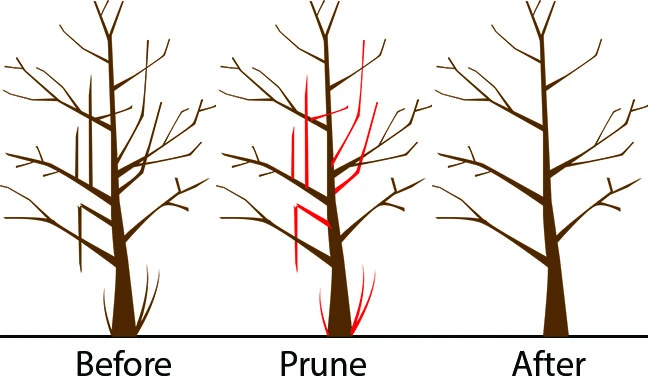

We can do this in MATLAB using the `cvloss` function and specifying a value for the `subtrees` parameter: 

% Assess how CV error changes with pruning the first 10 layers
cverror_prune10 = cvloss(Decision_Tree, 'Subtrees', 0:10); 
table([0:10]', cverror_prune10, 'VariableNames', {'Prune Level', 'CV Error'})

ans = 11×2 table
    Prune Level    CV Error
    ___________    ________

         0         0.048163
         1         0.048163
         2         0.047426
         3         0.046443
         4         0.045952
         5         0.045092
         6         0.044477
         7         0.043863
         8          0.04374
         9         0.042634
        10          0.04202


% Assess CV error for all pruning levels
cverror_pruneAll = cvloss(Decision_Tree, 'Subtrees', 'all'); 
table([0:numel(cverror_pruneAll)-1]', cverror_pruneAll, 'VariableNames', {'Prune Level', 'CV Error'})

ans = 24×2 table
    Prune Level    CV Error
    ___________    ________

         0         0.049023
         1           0.0489
         2         0.048777
         3          0.04804
         4         0.047795
         5         0.047303
         6         0.046812
         7         0.046443
         8         0.045092
         9         0.043863
        10         0.043494
        11         0.042388
        12         0.041528
        13          0.04116
        14         0.040914
        15         0.038825


% Determine the best pruning level
[~, ~, ~, Best_prune_level] = cvloss(Decision_Tree, 'Subtrees', 'all')

Best_prune_level = 22

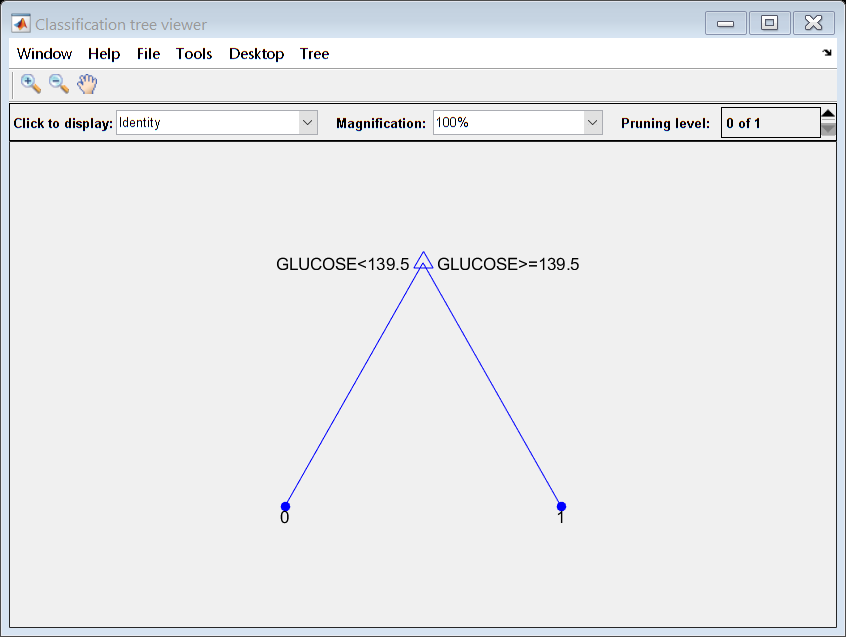

% Prune tree based on optimal level
pruned_tree = prune(Decision_Tree, 'Level', Best_prune_level); 
view(pruned_tree, 'Mode', 'Graph')

### **Hyperparameter tuning: controlling tree "leafiness"**

When you grow a decision tree, consider its simplicity and predictive power. A deep tree with many leaves is usually highly accurate on the training data. However, the tree is not guaranteed to show a comparable accuracy on an independent test set. 

A leafy tree tends to overtrain (or **overfit**), and its test accuracy is often far less than its training (resubstitution) accuracy. In contrast, a shallow tree does not attain high training accuracy, but can be more **robust** — its training accuracy could be close to that of a representative test set. Also, a shallow tree is easy to interpret. 

If you do not have enough data for training and testing, estimate tree accuracy through cross-validation.

`fitctree` has three name-value pair arguments that control the depth of resulting decision trees:

- `MaxNumSplits` — The maximal number of branch node splits is `MaxNumSplits` per tree. Set a large value for `MaxNumSplits` to get a deep tree. The default is `size(X,1) – 1`.

- `MinLeafSize` — Each leaf has at least `MinLeafSize` observations. Set small values of `MinLeafSize` to get deep trees. The default is `1`.

- `MinParentSize` — Each branch node in the tree has at least `MinParentSize` observations. Set small values of `MinParentSize` to get deep trees. The default is `10`.

% Build a tree with MinLeafSize = 10 and evaluate its training error via CV
tree = fitctree(Xtrain, Ytrain, 'CrossVal', 'On', 'MinLeafSize', 10);
error = kfoldLoss(tree)

error = 0.0364

% Build a tree with MinLeafSize = 2 and evaluate its training error via CV
tree = fitctree(Xtrain, Ytrain, 'CrossVal', 'On', 'MinLeafSize', 2);
error = kfoldLoss(tree)

error = 0.0448

The `fitctree` function also provides the option to automatically optimize model hyperparameters: 

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.044231 |     0.23994 |    0.044231 |    0.044231 |            4 |


|    2 | Accept |    0.045583 |     0.17021 |    0.044231 |    0.044905 |          432 |


|    3 | Accept |    0.045583 |      0.1372 |    0.044231 |    0.044232 |         2704 |


|    4 | Best   |    0.035508 |        0.21 |    0.035508 |    0.035511 |           44 |


|    5 | Accept |    0.035508 |      0.1988 |    0.035508 |    0.035508 |           58 |


|    6 | Accept |    0.035877 |     0.23059 |    0.035508 |    0.035463 |           23 |


|    7 | Accept |    0.035508 |     0.19836 |    0.035508 |    0.035494 |           35 |


|    8 | Accept |    0.035508 |     0.19287 |    0.035508 |    0.035497 |           50 |


|    9 | Accept |    0.035508 |     0.22689 |    0.035508 |    0.035512 |           78 |


|   10 | Accept |    0.035508 |     0.21148 |    0.035508 |    0.035493 |           68 |


|   11 | Accept |    0.035508 |      0.2097 |    0.035508 |    0.035499 |           68 |


|   12 | Accept |    0.035508 |     0.29009 |    0.035508 |    0.035499 |           39 |


|   13 | Accept |    0.035508 |     0.22882 |    0.035508 |    0.035501 |           68 |


|   14 | Accept |    0.035508 |     0.19715 |    0.035508 |    0.035501 |           33 |


|   15 | Accept |    0.035508 |     0.26168 |    0.035508 |    0.035501 |           38 |


|   16 | Accept |    0.035508 |     0.25725 |    0.035508 |    0.035503 |           70 |


|   17 | Accept |    0.035508 |     0.20522 |    0.035508 |    0.035503 |           38 |


|   18 | Accept |    0.048409 |     0.30925 |    0.035508 |    0.035501 |            1 |


|   19 | Accept |    0.035508 |     0.22769 |    0.035508 |    0.035502 |           64 |


|   20 | Accept |    0.045583 |     0.11478 |    0.035508 |    0.035502 |         4066 |


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |    0.045583 |     0.16723 |    0.035508 |    0.035501 |         1050 |


|   22 | Accept |    0.038334 |     0.21115 |    0.035508 |    0.035502 |            9 |


|   23 | Accept |    0.035508 |     0.23638 |    0.035508 |    0.035502 |           41 |


|   24 | Accept |    0.040668 |     0.21312 |    0.035508 |    0.035499 |          188 |


|   25 | Accept |     0.04546 |     0.25986 |    0.035508 |    0.035501 |            2 |


|   26 | Accept |    0.035508 |     0.19086 |    0.035508 |    0.035501 |           72 |


|   27 | Accept |    0.035508 |     0.19085 |    0.035508 |    0.035502 |           50 |


|   28 | Accept |    0.038334 |     0.20665 |    0.035508 |    0.035504 |           14 |


|   29 | Accept |    0.036122 |     0.21564 |    0.035508 |    0.035499 |           29 |


|   30 | Accept |    0.035508 |     0.22117 |    0.035508 |    0.035499 |          100 |


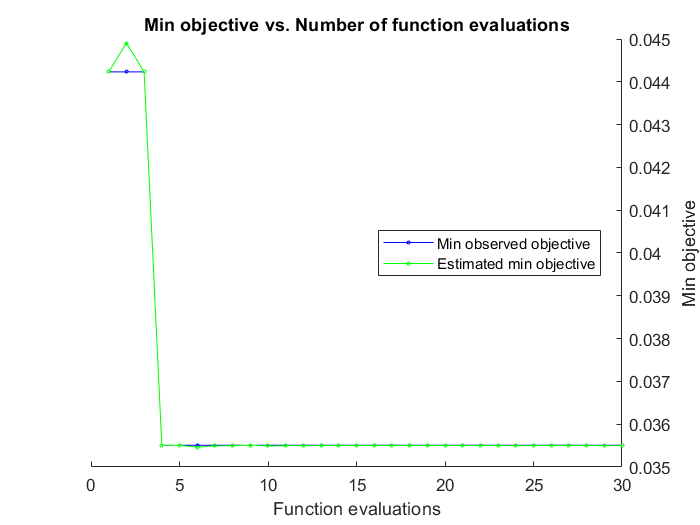

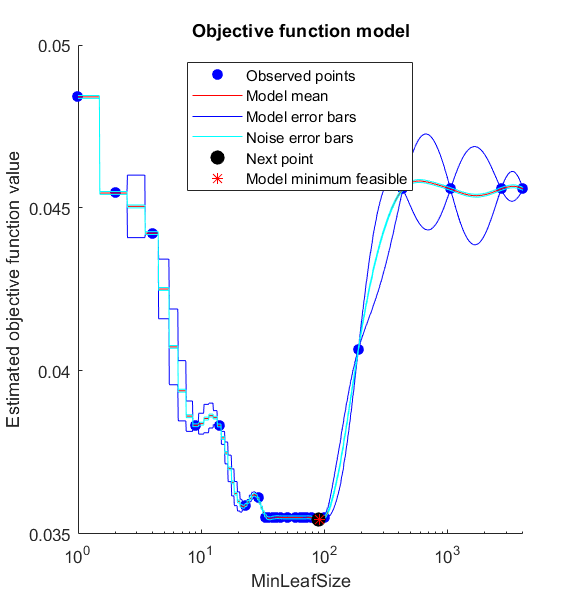


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 39.8753 seconds.
Total objective function evaluation time: 6.4309

Best observed feasible point:
    MinLeafSize
    ___________

        44     

Observed objective function value = 0.035508
Estimated objective function value = 0.035511
Function evaluation time = 0.21

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        38     

Estimated objective function value = 0.035499
Estimated function evaluation time = 0.21882



Mdl =   ClassificationTree
                       PredictorNames: {'RANDID'  'SEX'  'TOTCHOL'  'AGE'  'SYSBP'  'DIABP'  'CURSMOKE'  'CIGPDAY'  'BMI'  'BPMEDS'  'HEARTRTE'  'GLUCOSE'  'educ'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 8139
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Automatically find the best hyperparameters using CV
Mdl = fitctree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto')

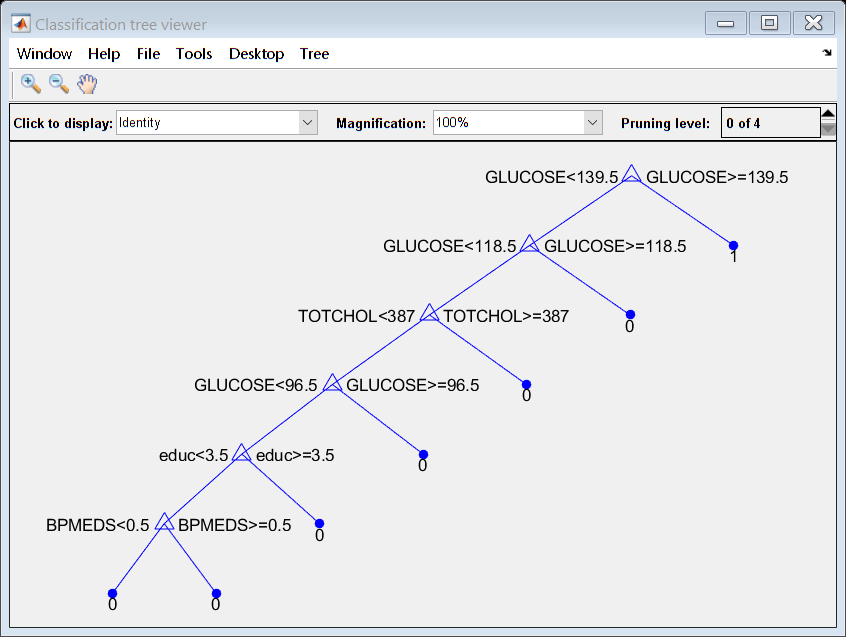

view(Mdl, 'mode', 'graph')

Note 1: click on leaves to see statistics for each category in the viewer.

Note 2: the decision tree can also output probabilities for the groups.

### Assessing DT model performance

For any predictive model, we always want to know how well it performs with unseen data. The metric we use to evaluate performance depends on what type of decision tree we built. For classification-based DT models, we can use: 

- **Accuracy**: the proportion of observations that were correctly classified

- **Precision**: the proportion of observations for a class that were actually correct

- **Recall**: the proportion of observations for a class that were correctly classified

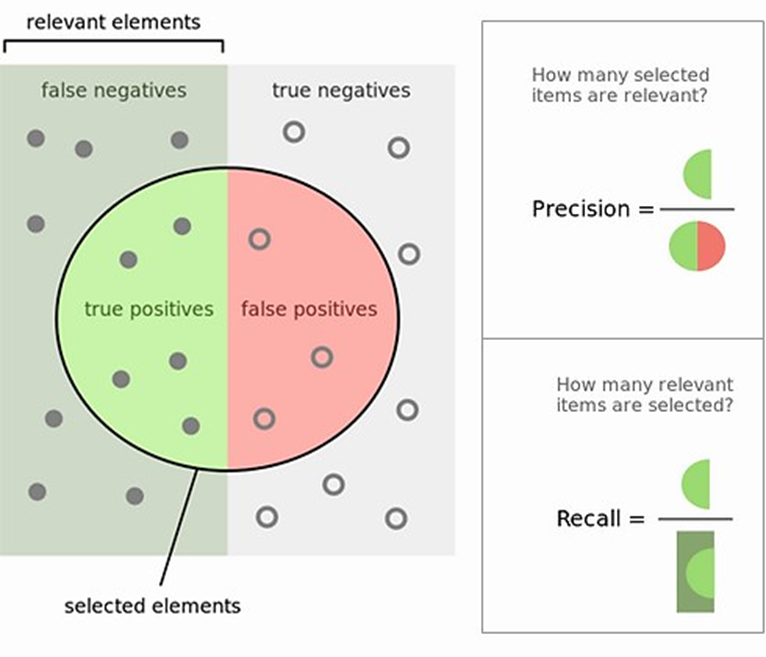

We can evaluate this information manually: 

% Determine predictions for test set
Ypred = predict(Mdl, Xtest);

% Assess overall accuracy and precision + recall for predicting diabetes
accuracy = mean(Ypred == Ytest)

accuracy = 0.9636

tp = sum(Ypred == 1 & Ytest == 1); 
fp = sum(Ypred == 1 & Ytest == 0); 
fn = sum(Ypred == 0 & Ytest == 1); 
precision = tp / (tp + fp)

precision = 0.7581

recall = tp / (tp + fn)

recall = 0.2956

Or we can use the built-in function `confusionchart` to visually interpret our classified performance: 

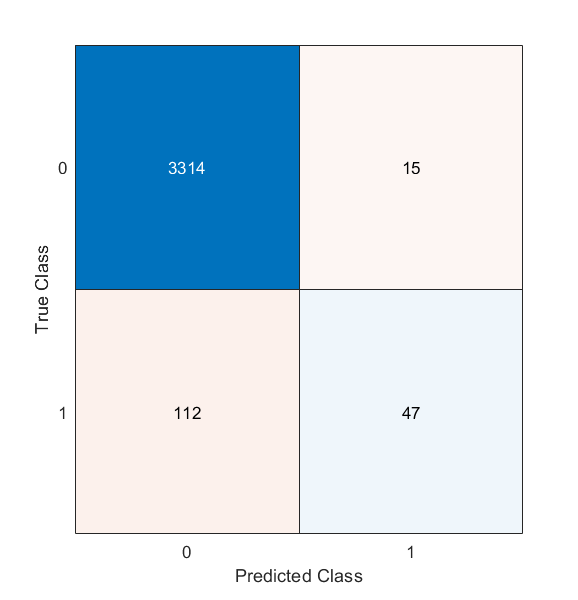

% Visualize confusion chart
confusionmat(Ytest, Ypred)

## Regression-based DT

For regression-based models, we can assess the **correlation** between model predictions and the actual output values. Regression-based decision trees can be built using the `fitrtree` function in MATLAB. The code below builds a regression-based DT model for predicting age based on patient data from the Framingham dataset: 

% Define input/output and training/testing sets
[X, Y] = deal(fram(:, [1:3 5:11]), fram.AGE); 
idx = crossvalind('HoldOut', numel(Y), 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

% Build regression model with automated hyperparameter optimization
regTree = fitrtree(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto'); 

% Predict outcome for test set
Ypred = predict(regTree, Xtest);

% Assess and visualize correlation between actual vs. predicted outcomes
[r, p] = corr(Ytest, Ypred); 
fprintf('R = %4.2f, p = %4.2e \n', r, p)
figure
scatter(Ytest, Ypred)

## Summary

- A decision tree is a non-linear predictive model that can be used for both classification and regression tasks

- Decision trees are a **white box** model, meaning that they are interpretable and explainable

- The structure of a decision tree is defined by rule-based nodes connected by edges

- The best decision tree attributes are determined by optimizing class separation (e.g. minimizing entropy)

- Hyperparameter tuning is needed to develop an optimal model that is generalizable to new data

- A deep tree tends to overfit to the training data; we can avoid this by defining hyperparameters that yield a shallow tree instead

### Built-in MATLAB functions introduced in this lesson:

- `fitctree`:      develops a classification-based decision tree

- `view`:              used to view the structure of the decision tree

- `resubLoss`:    calculates the resubstitution loss

- `cvloss`:          calculates the cross-validation loss

- `prune`:            prunes a tree given a specified level

- `kfoldloss`:    calculates the training error for a tree built using cross-validation

- `predict`:        generates predictions given a trained model and input (feature) data

- `fitrtree`:      develops a regression-based decision tree